# Examples for using the `cumulative_integral` function.

Copyright © 2022 Tamas Kis

## Example #1 - Cumulative integral of a data set.

*Consider the data set *$\mathbf{y}$ vs. $\mathbf{x}$:


$$\mathbf{x}=\left\lbrack \begin{array}{cccccc}
0\ldotp 12 & 0\ldotp 9 & 2\ldotp 1 & 2\ldotp 95 & 4\ldotp 03 & 4\ldotp 99
\end{array}\right\rbrack$$



$$\mathbf{y}=\left\lbrack \begin{array}{cccccc}
0 & 1\ldotp 2 & 8\ldotp 3 & 26\ldotp 1 & 65\ldotp 04 & 124\ldotp 43
\end{array}\right\rbrack$$


*Assume there is some underlying function *$y=f\left(x\right)$ that describes $y$ as a function of $x$. *Estimate and plot the following integral over the interval *$\left\lbrack 0\ldotp 12,4\ldotp 99\right\rbrack$:


$$\int_{0\ldotp 12}^x f\left(x\right)\;\textrm{dx}$$


First, input the data into MATLAB.

x = [0.12,0.9,2.1,2.95,4.03,4.99];
f = [0,1.2,8.3,26.1,65.04,124.43];

Estimating the integral above over the interval $\left\lbrack 0\ldotp 12,4\ldotp 99\right\rbrack$ is equivalent to evaluating the cumulative integral of the data set. Thus,

result = cumulative_integral(x,f);

Plotting,

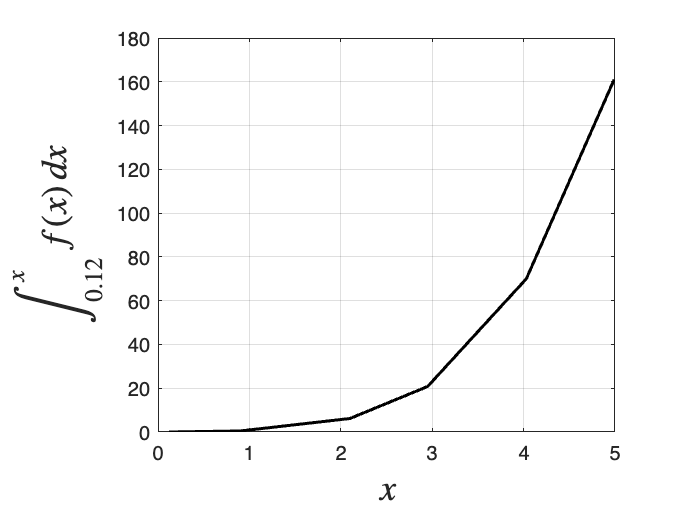

figure;
plot(x,result,'k','LineWidth',1.5);
grid on;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel("$\displaystyle\int_{0.12}^{x}f(x)\,dx$",'Interpreter','latex','FontSize',18);

## Example #2 - Cumulative integral of a known function.

*Consider the following function:*


$$f\left(x\right)=\int_2^x x^2 \;\textrm{dx}$$


*Use the *`cumulative_integral`* function to plot this function over the interval *$\left\lbrack 2,10\right\rbrack$*.*

First, let's rewrite this function as


$$f\left(x\right)=\int_2^x g\left(x\right)\;\textrm{dx}$$


where 


$$g\left(x\right)=x^2$$


Since the `cumulative_integral` function can only integrate data, we need to create a data set that stores evaluations of $g\left(x\right)$ at many points in the interval $\left\lbrack 2,10\right\rbrack$. To be as accurate as possible, we need a large number of points, so we use a small grid spacing of $\Delta x=0\ldotp 01$.

x = 2:0.01:10;
g = x.^2;

Evaluating the integral shown above over the interval $\left\lbrack 2,10\right\rbrack$ to find $f\left(x\right)$ (albeit in a discrete/numerical form),

f = cumulative_integral(x,g);

In this case, we can evaluate the integral in closed-form to find


$$f\left(x\right)=\frac{x^3 -8}{3}$$


Plotting our result, `f`, together with the exact $f\left(x\right)$ define above,

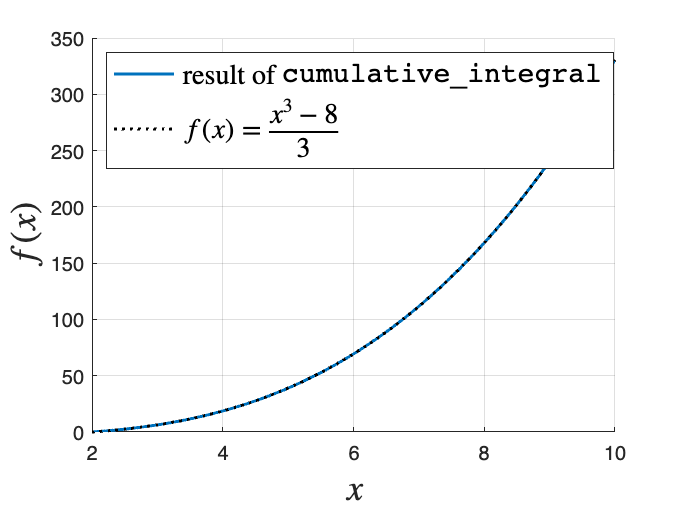

figure;
hold on;
plot(x,f,'LineWidth',1.5);
plot(x,(x.^3-8)/3,'k:','LineWidth',1.5);
hold off;
grid on;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel("$f(x)$",'Interpreter','latex','FontSize',18);
legend('result of \texttt{cumulative\_integral}',...
    '$f(x)=\displaystyle\frac{x^{3}-8}{3}$','Interpreter','latex',...
    'FontSize',14,'Location','northwest');

We can see that with a small grid spacing, the numerical result is nearly identical to the exact result.

## Example #3 - Rocket mass.

*A rocket has an initial mass of *$m_0 =20,000\;\textrm{kg}$, a dry (unfueled mass) of $m_f =5,000\;\textrm{kg}$,* and burns/expels propellant at a rate of *$\dot{m} =100t\;\textrm{kg}/\mathrm{s}$*, where *$t$* is time (in seconds). Plot the rocket mass as a function of time.*

The rocket mass as a function of time can be written as


$$m\left(t\right)=m_0 -\int_0^t \dot{\;m} \;\textrm{dt}$$


To begin with, we don't know how long it will take the rocket to burn its propellant. To ensure we capture the full burn time, we overestimate and guess it will take $500$ seconds. Defining the vectors $\mathbf{t}$ (to store an interval of discrete times) and $\dot{\mathbf{m}}$ (to store the corresponding mass flow rates) using a time step of $\Delta t=0\ldotp 01\;\mathrm{s}$,

t = 0:0.01:500;
mdot = 100*t;

Defining the initial and final mass,

m0 = 20000;
mf = 5000;

Evaluating (numerically) the expression for $m\left(t\right)$,

m = m0-cumulative_integral(t,mdot);

Since the rocket mass cannot decrease below $m_f$, we want to keep only that data where $m\left(t\right)>m_f$.

% combine data
data = [t;m];

% delete those columns where m < mf
data(:,data(2,:)<mf) = [];

% separate data
t = data(1,:);
m = data(2,:);

***Note: ****A quicker way to delete the necessary data using one line of code is to use the *`delete_data_points`* function (*[https://www.mathworks.com/matlabcentral/fileexchange/95113-delete-data-points-delete_data_points](https://www.mathworks.com/matlabcentral/fileexchange/95113-delete-data-points-delete_data_points)*). The syntax for this example would be *"`[t,m] = delete_data_points(t,m,'y < 5000')`".

Plotting the result,

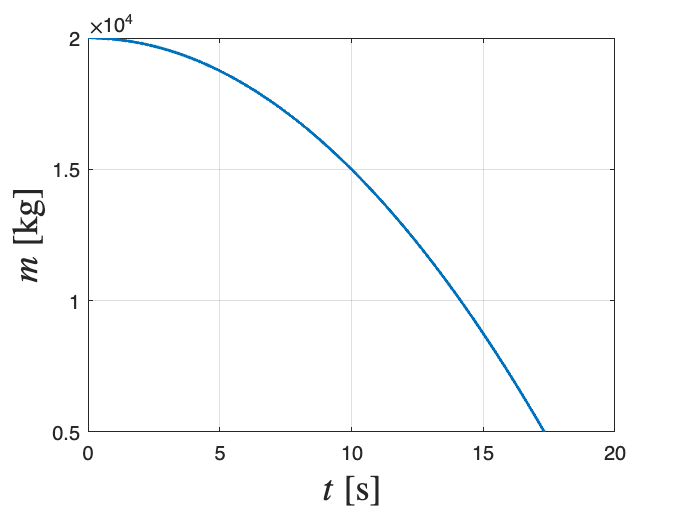

figure;
plot(t,m,'LineWidth',1.5);
grid on;
xlabel('$t\;[\mathrm{s}]$','Interpreter','latex','FontSize',18);
ylabel("$m\;[\mathrm{kg}]$",'Interpreter','latex','FontSize',18);